clear all;
load impulse_responses.mat
warning('off');


fs=16000;
num_samples=500000;
num_interferers=4;

[clean_speech,~] = audioread('clean_speech.wav');
[babble, ~] = audioread('babble_noise.wav');
[clean_speech_2, ~] = audioread('clean_speech_2.wav');
[artificial_nonstat_noise, ~] = audioread('aritificial_nonstat_noise.wav');
[speech_noise, ~] = audioread('Speech_shaped_noise.wav');

clean_speech = clean_speech(1:num_samples);
interference=[clean_speech_2(1:num_samples) babble(1:num_samples) artificial_nonstat_noise(1:num_samples) speech_noise(1:num_samples)].';

clean_speech_energy=sum(clean_speech.^2);
for i =1:size(interference,1)
    interference(i,:)=norm_sig(interference(i,:),clean_speech_energy);
end


M=4; % Number of microphones
sigma = 0.1; % Variance of the white noise
%read in impulse responses
H = struct2cell( load('impulse_responses.mat'));


%construct multiple sound_sources
x_time = zeros(4, num_samples);
s_time = zeros(4, num_samples); 
in_time=zeros(4, num_samples);

%speech2,babble, artificial, white
interference_ratio=[0.5,0.5,0.5,0.5];
SNR_mic_before = zeros(1, 4);
max_SNR=0;
SNR_factor=0;
noise_inter=zeros([num_samples,1]);


for i = 1:M
    target_signal=conv(clean_speech,H{5}(i,:),"same");
    for j=1:num_interferers
        interferer=conv(interference(j,:),H{j}(i,:),"same")*interference_ratio(j);
        noise_inter=noise_inter+interferer.';
    end
    % 
    % if i==1
    %     SNR_factor=sqrt(sum(target_signal.^2)/(10^(max_SNR/10)*sum(noise_inter.^2)));
    % end
    % noise_inter=noise_inter*SNR_factor;
    signal=target_signal+noise_inter;
    x_time(i,:) = signal;
    s_time(i,:) = target_signal;
    in_time(i,:)=noise_inter;
    
    % Calculate the SNR
    SNR_mic_before(i) = 10 * log10(sum(abs(target_signal).^2) / sum(abs(signal - target_signal).^2));
    filename = sprintf('microphone%d.wav', i);
    audiowrite(filename, signal, fs);
end

SNR_mic_before

SNR_mic_before =    -1.4443   -7.4325   -8.7966  -10.8780


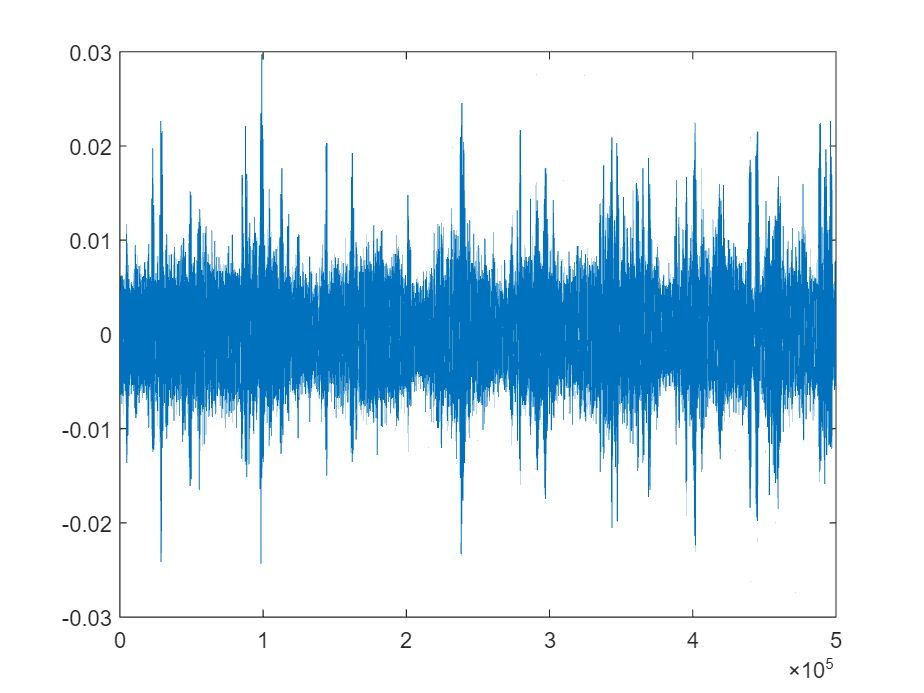

figure;
x_time=x_time/max(x_time(1,:));
plot(x_time(1,:))

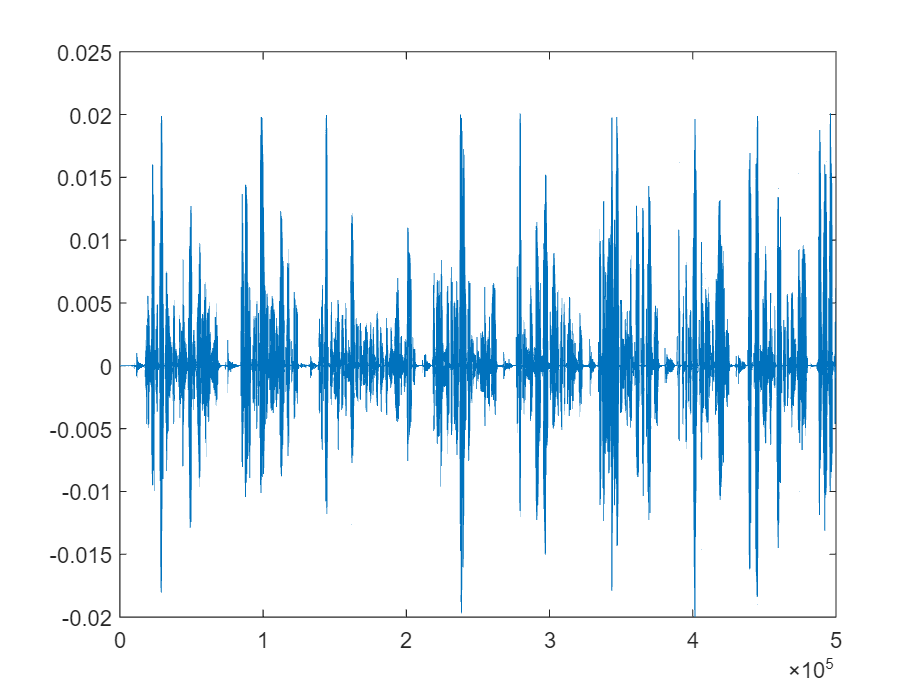


figure;
plot(s_time(1,:))

% Short time fourier transform
window_time=0.02;
K=window_time*fs;
Overlap=0.5;
[X, F, T] = stft(x_time.', fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength',320 );
L=size(X,2);
x_f_vad=stft(s_time(1,:).', fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength',320 );


% % Perform VAD
% threshold=0.005;
% vadResult = vad(x_f_vad, threshold);
% % Time axis for the original signal
% time = (0:length(x_time)-1) / fs;
% 
% % Time axis for the VAD result
% D = round(K * (1 - Overlap));  % Step size
% t_vad = (0:L-1) * D / fs;
% 
% 
% % Plotting
% figure;
% 
% % Plot the original signal
% 
% plot(time, x_time(1,:));
% xlabel('Time [s]');
% ylabel('Amplitude');
% legend('Audio Signal');
% hold on;
% % Plot the binary VAD result
% 
% plot(t_vad,(vadResult-0.5)*0.5, 'k', 'LineWidth', 1.5);
% xlabel('Time [s]');
% ylabel('VAD');
% title('Voice Activity Detection (VAD)');
% legend('VAD Result');
% hold off;


idx=detectSpeech(s_time(1,:)',16000,"Window",hann(K,'periodic'),'OverlapLength',K/2);
l_speech=VAD_matlab(s_time(1,:)',K,0.5,16000);
plot((l_speech), 'k', 'LineWidth', 1.5);

S_est = zeros(K, L);
R_x=zeros([4,4]);
R_n=zeros([4,4]);
R_x_tilde=zeros([4,4]);
alpha=0.9;
u=0.7;

alpha=0.8;
us_stois=[];
for u=0:4:20
    u
    for k = 1:K
        for l = 1:L
          curr_x=squeeze(X( k, l,:));
          if l==1
              R_n= curr_x*curr_x';
              R_x= curr_x*curr_x';
          else
                  if l_speech(l)==0
                      R_n = alpha.*R_x + (1-alpha).*curr_x*curr_x';                 
                  end
                R_x = alpha.*R_x + (1-alpha).*curr_x*curr_x';
          end
    
          %now to estimate the atf
            [U,V]=eig(R_x,R_n);
            % Extract eigenvalues
            eigenvalues = diag(V);
            [eig_sorted, sortedIndices] = sort(eigenvalues, 'descend');
            U_sorted = U(:, sortedIndices);
            a=U_sorted(:,1);
            sigma_s=(eig_sorted(1)-1);

            %calculate the RTF
            % R_x_inv=pinv(R_x);
            % a=a/a(1);
            % w = (R_x_inv *a ) / (a'*R_x_inv * a);
    
            % SDW
            R_n_inv=pinv(R_n);
            w=sigma_s*R_n_inv*a/((a'*R_n_inv*a)*(sigma_s+u*pinv(a'*R_n_inv*a)));
            
            %delay and sum beamformer
            % w=a/(a(1)*4);
    
            % % %MVDR beamformer
            % R_x_inv = pinv(R_x);
            % w = R_x_inv * a / (a' * R_x_inv * a);      
    
            S_est( k, l) = w' * curr_x;
        end
    end
    S_est(isnan(S_est))=0;
    S_est(isinf(S_est))=0;
    ss=real(istft(squeeze(S_est), fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength', 320));
    stoi1=stoi(clean_speech,ss,16000)
    stoi2=stoi(clean_speech,x_time(1,:),16000)
    us_stoi=[stois,[stoi1;stoi2]];
    
end

u = 0

S_est(isnan(S_est))=0;
ss=real(istft(squeeze(S_est), fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength', 320));
audiowrite('beamformed_output.wav', ss, fs);
plot(ss)
stoi(clean_speech,ss,16000)

stoi is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\fharr\OneDrive\Documents\Git\Array_Processing_proj\proj2

Change the MATLAB current folder or add its folder to the MATLAB path.

stoi(clean_speech,x_time(1,:),16000)


function signal_out = norm_sig(in_signal,target_energy)
    factor= sqrt(target_energy/sum(in_signal.^2));
    signal_out = in_signal *factor;
end
